# Practice 8 (G)

This version 08/08/2024

# Global Asset Allocation

## Miguel Ángel González Álvarez

## Emilly Noelia Villacís Recalde

## Quinten Woumans

## Edoardo Anfelli

## Stokely Ross

## Part 1

### Global Asset Allocation

You work for the Global Asset Allocation department of the Norwegian Oil Fund. The fund is long-only with no borrowing or leverage. You are designing the asset allocation targets for 2024. The asset classes you consider are Real Estate, Fixed Income, Large-Cap Stocks and Small-Cap stocks. Your initial proposal for target proportions are 5%, 25%, 50% and 20%, respectively. Using monthly data during 2010-2022, select four global ETFs corresponding to the four asset classes. 

## **Questions**

**(2 Points)**

- Build the Markowitz optimal portfolio (M), that should have no more than 70% of the portfolio in equities, and no more than 20% of the portfolio in emerging equities. (1 Point)

- Compare M against your initial proposal portfolio. What are the main differences?. Would you change your asset allocations? Why?. (1 Point)

# Write your answer here

The Markowitz optimal portfolio (M) adheres to the specified constraints, which require that no more than 70% of the portfolio be invested in equities and no more than 20% in Small-Cap Equities. In this portfolio, 50% is allocated to Large-Cap Equities, and 20% to Small-Cap Equities, fulfilling the equity allocation limits. Fixed Income receives 30% of the allocation, while Real Estate has no allocation in the optimal portfolio. These adjustments result in a portfolio that maintains the required exposure limitations across asset classes.

When comparing the optimal portfolio with the initial proposal portfolio, there are slight differences in both expected return and risk. The optimal portfolio’s expected excess return is 0.2766%, which is marginally higher than the initial portfolio’s expected return of 0.2714%. Additionally, the optimal portfolio has a lower risk (standard deviation of 3.5381%) compared to the initial portfolio’s risk of 3.6879%. These small improvements indicate that the optimal portfolio provides a slightly better trade-off between return and risk than the initial proposal, aligning with the goal of maximizing returns while controlling for risk.

Examining the risk-adjusted returns through the Sharpe ratio, the optimal portfolio achieves a Sharpe ratio of 0.0784, slightly higher than the initial portfolio’s Sharpe ratio of 0.0736. However, both Sharpe ratios are relatively low, indicating limited risk-adjusted return. Moreover, the p-values for both Sharpe ratios are above the target p-value meaning neither Sharpe ratio is statistically significantly different from zero. This lack of statistical significance implies that there is no strong evidence that either portfolio provides excess returns beyond what might be expected by chance.

Given the results, the recommendation suggests considering the optimal portfolio due to its marginally higher expected return and lower risk, even though the difference is not statistically significant. This recommendation is driven by the optimal portfolio’s slight advantage in risk-return characteristics, albeit minimal. The lack of statistical significance in the Sharpe ratios implies that the decision to switch to the optimal portfolio should be weighed carefully, as the improvement may not yield substantial practical benefits. If small incremental gains in risk-adjusted return are valuable and transaction costs are minimal, the optimal portfolio might be preferable. However, if other strategic considerations, such as liquidity or specific asset class preferences, the initial portfolio remains a valid choice.

clear all
% Load data from the Excel file
data = readtable('Question1Data2.xlsx');

% Adjust the risk-free rate from annual to monthly rate in decimal form
data.rf = (1 + data.rf).^(1/12) - 1;

% Compute excess returns by subtracting the risk-free rate from each asset's return
ExcessReturns = [data.IFGL - data.rf, data.LQD - data.rf, data.ACWI - data.rf, data.IWM - data.rf];

% Define asset list
Asset = { 'Real Estate', 'Fixed Income', 'Large-Cap Equities', 'Small-Cap Equities' };

% Compute mean excess returns and covariance matrix
AssetMean = mean(ExcessReturns)';       % Mean returns as a column vector
AssetCovar = cov(ExcessReturns);        % Covariance matrix of excess returns

% Initial proposal portfolio weights
InitPortWeights = [ 0.05; 0.25; 0.50; 0.20 ];

% Create a table for the initial portfolio
TPortf = table(InitPortWeights, 'RowNames', Asset, 'VariableNames', {'InitPort'});
disp('Initial Proposal Portfolio:');

Initial Proposal Portfolio:


disp(TPortf);

                          InitPort
                          ________

    Real Estate             0.05  
    Fixed Income            0.25  
    Large-Cap Equities       0.5  
    Small-Cap Equities       0.2  




% Create Portfolio object
p = Portfolio('Name', 'Global Asset Allocation Portfolio', 'AssetList', Asset);

% Set default constraints (weights sum to 1, weights >= 0)
p = setDefaultConstraints(p);

% Set group constraints
% Equities (Large-Cap and Small-Cap Equities) total weight <= 70%
p = setGroups(p, [0 0 1 1], [], 0.70);

%Constraints
p = setGroups(p, [ 0, 0, 1, 1 ], [], 0.70);
p = addGroups(p, [ 0, 0, 0, 1 ], [], 0.20);

% Set asset moments (mean returns and covariance)
p = setAssetMoments(p, AssetMean, AssetCovar);

% Display the portfolio object
disp('Portfolio Object with Constraints:');

Portfolio Object with Constraints:


disp(p);

  Portfolio with properties:

                       BuyCost: []
                      SellCost: []
                  RiskFreeRate: []
                     AssetMean: [4×1 double]
                    AssetCovar: [4×4 double]
                 TrackingError: []
                  TrackingPort: []
                      Turnover: []
                   BuyTurnover: []
                  SellTurnover: []
                          Name: 'Global Asset Allocation Portfolio'
                     NumAssets: 4
                     AssetList: {'Real Estate'  'Fixed Income'  'Large-Cap Equities'  'Small-Cap Equities'}
                      InitPort: []
                   AInequality: []
                   bInequality: []
                     AEquality: []
                     bEquality: []
                    LowerBound: [4×1 double]
                    UpperBound: []
                   LowerBudget: 1
                   UpperBudget: 

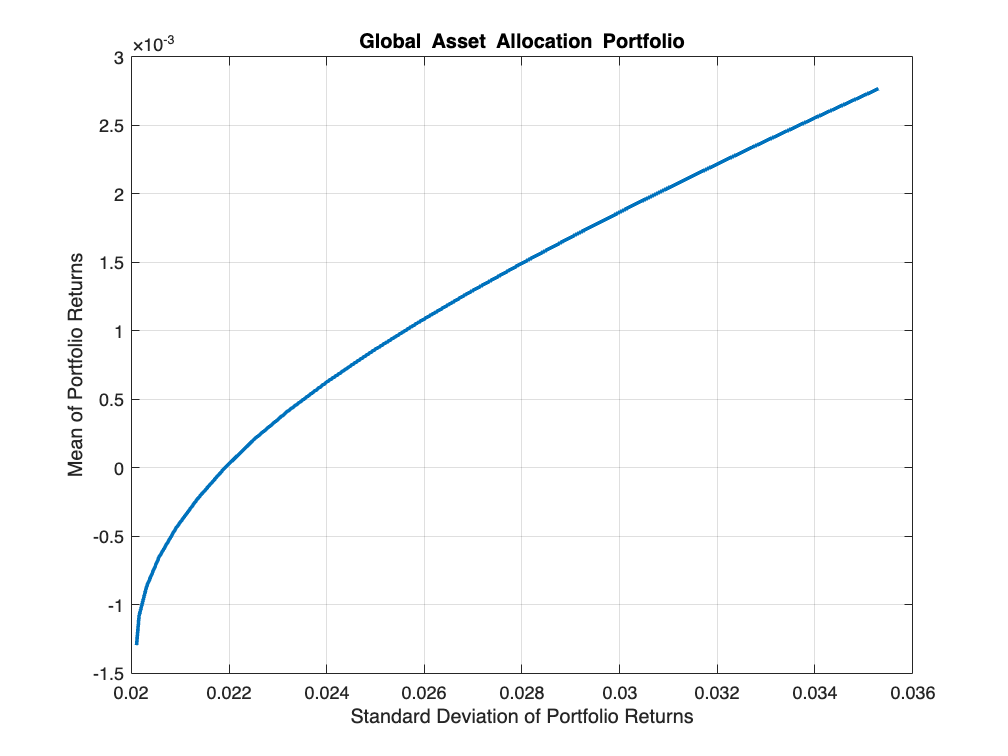


% Estimate the efficient frontier
[prisk, pret] = p.plotFrontier(20);


% Estimate the portfolio that maximizes the Sharpe ratio
pwgtMaxSR = p.estimateMaxSharpeRatio;

% Compute expected return and risk of the optimal portfolio
[optRisk, optRet] = p.estimatePortMoments(pwgtMaxSR);
optSR = optRet / optRisk;

% Compute expected return and risk of the initial portfolio
[initRisk, initRet] = p.estimatePortMoments(InitPortWeights);
initSR = initRet / initRisk;

% Display optimal portfolio weights
disp('Optimal Portfolio Weights (M):');

Optimal Portfolio Weights (M):


OptimalPortfolio = table(Asset', pwgtMaxSR, 'VariableNames', {'Asset', 'Weight'});
disp(OptimalPortfolio);

            Asset               Weight  
    ______________________    __________

    {'Real Estate'       }    6.3344e-14
    {'Fixed Income'      }           0.3
    {'Large-Cap Equities'}           0.5
    {'Small-Cap Equities'}           0.2




% Compute p-values for Sharpe ratios
% Number of observations
N = height(data);

% Standard errors of Sharpe ratios
optSE_SR = sqrt((1 + (optSR^2) / 2) / N);
initSE_SR = sqrt((1 + (initSR^2) / 2) / N);

% t-statistics for Sharpe ratios
opt_t_SR = optSR / optSE_SR;
init_t_SR = initSR / initSE_SR;

% p-values for Sharpe ratios (two-tailed test)
opt_p_value = 2 * (1 - tcdf(abs(opt_t_SR), N - 1));
init_p_value = 2 * (1 - tcdf(abs(init_t_SR), N - 1));

% Display expected returns and risks
fprintf('\nOptimal Portfolio Expected Excess Return: %.4f%%\n', optRet * 100);


Optimal Portfolio Expected Excess Return: 0.2766%


fprintf('Optimal Portfolio Risk (Std Dev): %.4f%%\n', optRisk * 100);

Optimal Portfolio Risk (Std Dev): 3.5301%


fprintf('\nOptimal Portfolio Sharpe Ratio: %.4f\n', optSR);


Optimal Portfolio Sharpe Ratio: 0.0784


fprintf('\nOptimal Portfolio Sharpe Ratio p-value: %.4f\n', opt_p_value);


Optimal Portfolio Sharpe Ratio p-value: 0.3300



fprintf('\nInitial Portfolio Expected Excess Return: %.4f%%\n', initRet * 100);


Initial Portfolio Expected Excess Return: 0.2714%


fprintf('Initial Portfolio Risk (Std Dev): %.4f%%\n', initRisk * 100);

Initial Portfolio Risk (Std Dev): 3.6879%


fprintf('Initial Portfolio Sharpe Ratio: %.4f\n', initSR);

Initial Portfolio Sharpe Ratio: 0.0736


fprintf('Initial Portfolio Sharpe Ratio p-value: %.4f\n', init_p_value);

Initial Portfolio Sharpe Ratio p-value: 0.3601



% Decide whether to change asset allocations based on comparison
if optRet > initRet && optRisk <= initRisk
    disp('Recommendation: Consider changing the asset allocations to the optimal portfolio.');
else
    disp('Recommendation: The initial portfolio may be preferred based on risk-return preferences.');
end

Recommendation: Consider changing the asset allocations to the optimal portfolio.


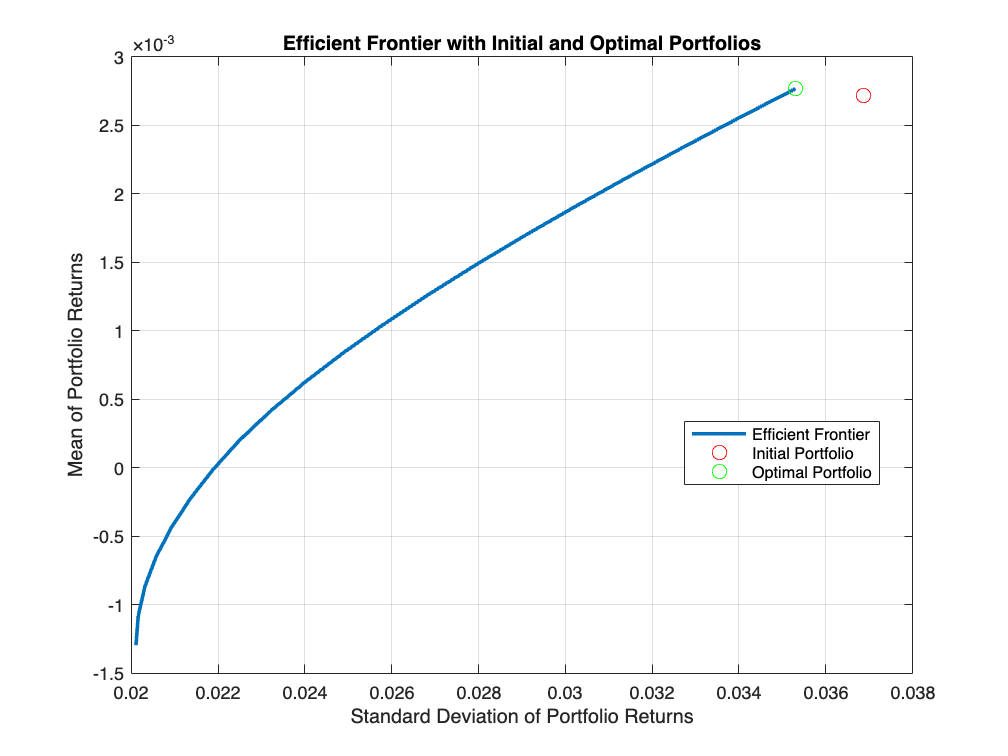


% Plot efficient frontier and mark the initial and optimal portfolios
figure;
p.plotFrontier(20);
hold on;
plot(initRisk, initRet, 'ro', 'MarkerSize', 8, 'DisplayName', 'Initial Portfolio');
plot(optRisk, optRet, 'go', 'MarkerSize', 8, 'DisplayName', 'Optimal Portfolio');
legend('show', 'Location', 'Best');
title('Efficient Frontier with Initial and Optimal Portfolios');
hold off;

## Part 2

### Foreign and Domestic Investments

You work for an investment and advisory firm located in San Francisco (California, USA). An offshore Hedge Fund HF offers you a new financial contract named TopSwiss. The price of TopSwiss is $1000*TS, where TS is the average correlation (during the last three years) between the return in the exchange rate of the US dollar and the Swiss Franc ($/SF) and the Swiss stock market returns. The HF offers you 100,000 units of this contract that you may sell later to your retail investors. The HF asks for a unit price of $857, including a special rebate. The HF points out that the average yearly return in Swiss Francs of the Swiss Stock Market Index (SSMI) in the last five years has been around 10%. Besides, the US Dollar has suffered a persistent depreciation against the Swiss Franc of about 2% yearly. 

After doing some research, you estimate that the annual volatility of the returns of the Swiss Stock Market Index (SSMI) is 10%, and the annual volatility of the exchange rate $/SF is 5%. You also estimate that the annual volatility of an investment in SMMI by American-located investors has been 14% on average during the last five years. 

###  **Questions**

**(1 Point)**

- Do you accept or refuse the Hedge Fund offer? Explain your decision, including your valuation of TopSwiss. 

# Write your answer here

After reviewing the Hedge Fund's offer for the TopSwiss contract, I have decided to refuse it. The primary reason is that the contract is overpriced based on our valuation.

The TopSwiss contract is priced at $1,000 multiplied by TS, which represents the average correlation between the US dollar to Swiss Franc exchange rate returns and the Swiss stock market returns over the past three years. Using the provided data on annual volatilities and returns, we estimated TS to be approximately 0.71.

This estimation considers the annual volatility of the Swiss Stock Market Index (SSMI) returns at 10%, the exchange rate volatility at 5%, and the volatility of SSMI returns for US investors at 14%. Our analysis suggests that the fair value of the TopSwiss contract is around $710 per unit.

However, the Hedge Fund is offering the contract at $857 per unit, which is significantly higher than our calculated fair value. This means we would be overpaying by about $147 per unit, amounting to a substantial overpayment for 100,000 units.

Considering this discrepancy, accepting the offer would not be financially prudent for our firm or beneficial for our retail investors. The contract's overpricing outweighs any potential advantages highlighted by the Hedge Fund, such as past market performance and currency depreciation.

In conclusion, due to the overvaluation of the TopSwiss contract, I recommend declining the Hedge Fund's offer.

To go for further negotiation with the Hedge Fund a good starting price would be $745.4911. This is the upper limit of the confidence interval of the fair value, assuming daily data and a confidence interval of 95%. 

% Valuation 
sigma_SSMI = 0.10;
sigma_SF = 0.05;
sigma_SSMIUS = 0.14;

Cov_SSMI_SF = (sigma_SSMIUS^2 - sigma_SSMI^2 - sigma_SF^2)/2 ;

TS = Cov_SSMI_SF / (sigma_SSMI*sigma_SF);

Price_TS = 1000*TS

Price_TS = 710.0000


% Price_TS = $710
% Overvaluation of $857 - $710 = $147

% Confidence interval for counter offer 
% 3 years of data and assuming daily data 

STD_p = (1-(0.71)^2)/(sqrt(750))

STD_p = 0.0181


% choosing a confidence interval of 95% 
ul = 710 + 1.96*(1000*STD_p)

ul = 745.4911

ll = 710 - 1.96*(1000*STD_p)

ll = 674.5089


fprintf('\n A good starting point to go back to the HF for further negotiation would be: $%.4f\n', ul);


 A good starting point to go back to the HF for further negotiation would be: $745.4911


## Part 3

### Replicating Global Funds

Your are evaluating several global asset allocation funds offered by Fidelity Investments. After reviewing several funds, you focus on the **Fidelity Global Asset Allocation Fund (https://www.fidelity.ca/en/products/funds/am/), FGAAFF.**

## **Questions**

**(1 Point)**

- Describe all the main characteristics of FGAAFF you deem relevant for a prospective investor.  The FGAAFF Expense ratio is 2.26%. Replicate a portfolio mimicking the FGAAFF structure and performance using ETFs but with an expense ratio that should be at least half of what FGAAFF charges to investors. (1 Points)

# Write your answer here

**Key Characteristics of the Fidelity Global Asset Allocation Fund (FGAAFF)**

The Fidelity Global Asset Allocation Fund (FGAAFF) is a globally diversified fund designed for investors seeking balanced exposure to equities, fixed income, and money market assets. The fund's primary goal is to provide long-term capital growth and income by investing across a broad range of asset classes. It tries to maximize risk-adjusted return potential through tactical global asset allocation. Furthermore the fund combines the flexibility of tactical asset allocation with Fidelity’s disciplined ‘bottom up’ investment approach to deliver maximized risk-adjusted return potential. Its neutral allocation targets 65% in equities, 30% in fixed income, and 5% in money market instruments, though this mix can vary based on the portfolio manager’s outlook and market conditions. FGAAFF's geographic allocation emphasizes the United States but also includes developed and emerging markets worldwide. With a low-to-medium risk rating, FGAAFF is suitable for investors with a medium to long-term investment horizon who are prepared to handle moderate volatility for potential growth.

One significant factor for prospective investors to consider is the fund’s expense ratio of 2.26%. This management fee reduces the net returns, which may impact overall investment performance over the long term. The fund’s trailing commission, paid out to dealers for their advisory services, contributes to this relatively high expense ratio. As a result, cost-conscious investors may seek to replicate the fund’s structure and performance using a mix of low-cost ETFs to reduce management fees while maintaining similar exposure to global equities, bonds, and money markets.

**Strategy for Replicating FGAAFF Using ETFs**

To create a lower-cost alternative to FGAAFF, we can construct a portfolio with a similar asset allocation and geographic diversification using exchange-traded funds (ETFs). The goal is to replicate FGAAFF’s structure with an expense ratio of 1.13% or less (half of FGAAFF’s 2.26%) by choosing ETFs with lower management fees. Here’s how the portfolio can be structured to mirror FGAAFF's asset allocation:

1. Equity Allocation (65%): The equity portion of FGAAFF is globally diversified, with significant exposure to U.S. equities and developed markets outside the U.S., as well as a smaller allocation to emerging markets. To replicate this:

- iShares Core S&P 500 UCITS ETF (CSPX): Allocating 32.5% of the total portfolio to this ETF provides substantial U.S. exposure, reflecting FGAAFF’s emphasis on the U.S. stock market.

- iShares Core MSCI Europe UCITS ETF (IMEA): With a 13% allocation, this ETF offers exposure to developed European markets, aligning with FGAAFF’s regional diversification.

- iShares MSCI Japan UCITS ETF (CSJP): A 6.5% allocation to this ETF ensures specific exposure to Japanese equities, as Japan is a significant component of the global market.

- iShares MSCI UK UCITS ETF (CSUK): Allocating 6.5% to UK equities provides balanced exposure to developed markets beyond the U.S. and Europe.

- iShares Core MSCI Emerging Markets IMI UCITS ETF (EIMI): With 6.5% of the portfolio, this ETF captures emerging market exposure, reflecting FGAAFF’s limited allocation to emerging economies for diversification.

2. Fixed Income Allocation (30%): The fixed income portion of FGAAFF focuses on global bonds, primarily using the Fidelity Global Bond Fund, which follows the Bloomberg Global Aggregate Bond Index. To replicate this exposure cost-effectively:

- SPDR Bloomberg Global Aggregate Bond UCITS ETF (GLAG): A 30% allocation to this ETF provides exposure to a globally diversified portfolio of investment-grade bonds across developed and emerging markets. This ETF’s broad scope aligns well with FGAAFF’s fixed-income objectives, ensuring that the fixed income portion of the portfolio captures global bond performance while keeping management fees low.

3. Money Market Allocation (5%): FGAAFF allocates a small portion to cash and money market instruments for stability and liquidity. The fund uses primarily the Fidelity Canadian Money Market Investment Trust. This allocation is essential for preserving capital and minimizing volatility. To replicate this exposure coast-effectively: 

- iShares Premium Money Market ETF (CMR): By allocating 5% to this money market ETF, we provide the portfolio with a cash-like asset that can act as a buffer against market fluctuations. This ETF mirrors FGAAFF’s low-risk cash allocation strategy and maintains liquidity, which is important for investors seeking to preserve a portion of their capital.

**Performance Comparison **

Now the cost-effectiveness and performance trade-offs between the Fidelity Global Asset Allocation Fund (FGAAFF) and the mimicking ETF portfolio need to be assessed. FGAAFF achieves a 5-year annualized return of 5.85% with a standard deviation of 9.30, resulting in a Sharpe Ratio of 0.63. However, the fund’s high expense ratio of 2.26% significantly impacts its net returns. In contrast, the mimicking ETF portfolio, with a lower expense ratio of 0.36%, produces a 5-year annualized return of 4.51% and a slightly higher standard deviation of 12.32, leading to a Sharpe Ratio of 0.366. While the ETF portfolio achieves similar asset allocation and global exposure, its lower cost structure provides a substantial advantage over time, despite delivering a slightly lower risk-adjusted return. This approach makes it an appealing choice for investors prioritizing cost savings.

**Benefits of This Replication Strategy**

This ETF-based portfolio effectively mirrors FGAAFF’s structure at a lower cost, with an expense ratio target of 0.36%. Each ETF in the portfolio has been chosen to match FGAAFF’s asset allocation and geographic distribution while maintaining a low management expense ratio. The use of broad, diversified ETFs from reputable providers ensures that the portfolio captures similar market exposure to FGAAFF, enabling it to mimic both the risk profile and the performance characteristics of the original fund.

This approach offers a significant cost advantage, as the lower expense ratio can increase net returns over time, making it an attractive alternative for cost-sensitive investors. Moreover, the portfolio’s allocations provide a balanced exposure to global equities, fixed income, and money market instruments, making it suitable for investors with a medium to long-term horizon who seek moderate growth with manageable volatility.

% Expense ratio FGAAFF
ER_FGAAF=0.026;


% Monthly calculation 

% Load data from the Excel file
data2 = readtable('Question3Data.xlsx');

% Adjust the risk-free rate from annual to monthly rate in decimal form
data2.rf = (1 + data2.rf).^(1/12) - 1;

% Compute excess returns by subtracting the risk-free rate from each asset's return
ExcessReturns2 = [data2.SPFB - data2.rf, data2.CMR - data2.rf, data2.IVV - data2.rf,data2.IEMG - data2.rf, data2.IEUR - data2.rf, data2.EWJ - data2.rf,data2.EWU - data2.rf];

% Define asset list
Asset2 = { 'Fixed Income', 'Money Market', 'S&P 500', 'Emerging Market', 'MSCI Europe','MSCI Japan','MSCI UK'  };

% Compute mean excess returns and covariance matrix
AssetMean2 = mean(ExcessReturns2)';       % Mean returns as a column vector
AssetCovar2 = cov(ExcessReturns2);        % Covariance matrix of excess returns

% Initial proposal portfolio weights
InitPortWeights2 = [ 0.30; 0.05; 0.325; 0.065; 0.13;0.065;0.065 ];

% Create a table for the initial portfolio
Portf = table(InitPortWeights2, 'RowNames', Asset2, 'VariableNames', {'InitPort'});
disp('Initial Proposal Portfolio:');

Initial Proposal Portfolio:


disp(Portf);

                       InitPort
                       ________

    Fixed Income          0.3  
    Money Market         0.05  
    S&P 500             0.325  
    Emerging Market     0.065  
    MSCI Europe          0.13  
    MSCI Japan          0.065  
    MSCI UK             0.065  





% Compute time series of portfolio excess returns
PortExcessReturns = ExcessReturns2 * InitPortWeights2;

% Compute mean and standard deviation of portfolio excess returns
PortMean = mean(PortExcessReturns);
PortStdDev = std(PortExcessReturns);

% Compute Sharpe ratio
PortSharpeRatio = PortMean / PortStdDev;

% Number of observations
N = length(PortExcessReturns);

% Compute t-statistic for Sharpe ratio
t_stat = PortSharpeRatio * sqrt(N);

% Compute p-value
p_value = 2 * (1 - normcdf(abs(t_stat)));

% Display results
fprintf('Portfolio Expected Return: %.4f\n', PortMean);

Portfolio Expected Return: 0.0037


fprintf('Portfolio Standard Deviation: %.4f\n', PortStdDev);

Portfolio Standard Deviation: 0.0356


fprintf('Portfolio Sharpe Ratio: %.4f\n', PortSharpeRatio);

Portfolio Sharpe Ratio: 0.1036


fprintf('p-value for Sharpe Ratio: %.4f\n', p_value);

p-value for Sharpe Ratio: 0.4183


% Annual calculation

% Load data from the Excel file
data2 = readtable('Question3Data.xlsx');

% Adjust the risk-free rate from annual to monthly rate in decimal form
data2.rf = (1 + data2.rf).^(1/12) - 1;

% Compute asset returns (not excess returns)
Returns2 = [data2.SPFB, data2.CMR, data2.IVV, data2.IEMG, data2.IEUR, data2.EWJ, data2.EWU];

% Compute excess returns by subtracting the risk-free rate from each asset's return
ExcessReturns2 = [data2.SPFB - data2.rf, data2.CMR - data2.rf, data2.IVV - data2.rf,data2.IEMG - data2.rf, data2.IEUR - data2.rf, data2.EWJ - data2.rf,data2.EWU - data2.rf];

% Define asset list
Asset2 = { 'Fixed Income', 'Money Market', 'S&P 500', 'Emerging Market', 'MSCI Europe','MSCI Japan','MSCI UK'  };

% Initial proposal portfolio weights
InitPortWeights2 = [ 0.30; 0.05; 0.325; 0.065; 0.13;0.065;0.065 ];

% Compute time series of portfolio returns (total returns)
PortReturns = ExcessReturns2 * InitPortWeights2;

% Compute average monthly return of the portfolio
PortMeanReturn = mean(PortReturns);

% Annualize the average monthly return
AnnualPortReturn = (1 + PortMeanReturn) ^ 12 - 1;

% Compute standard deviation of monthly portfolio returns
PortStdDevMonthly = std(PortReturns);

% Annualize the standard deviation
PortStdDevAnnual = PortStdDevMonthly * sqrt(12);

% Compute the annualized Sharpe Ratio
AnnualSharpeRatio = AnnualPortReturn / PortStdDevAnnual;

% Number of observations (months)
N = length(PortReturns);

% Compute the t-statistic for the Sharpe Ratio
t_stat = AnnualSharpeRatio * sqrt(N);

% Compute the p-value for the t-statistic
p_value = 2 * (1 - normcdf(abs(t_stat)));

% Display the annual return
fprintf('Portfolio Annual Return: %.4f%%\n', AnnualPortReturn * 100);

Portfolio Annual Return: 4.5146%


fprintf('Portfolio Annualized Standard Deviation: %.4f%%\n', PortStdDevAnnual * 100);

Portfolio Annualized Standard Deviation: 12.3240%


fprintf('Portfolio Annualized Sharpe Ratio: %.4f\n', AnnualSharpeRatio);

Portfolio Annualized Sharpe Ratio: 0.3663


fprintf('t-statistic for Sharpe Ratio: %.4f\n', t_stat);

t-statistic for Sharpe Ratio: 2.8611


fprintf('p-value for Sharpe Ratio: %.4f\n', p_value);

p-value for Sharpe Ratio: 0.0042


## Local Functions

function displayReturns(pret1)
fprintf('Annualized Portfolio Returns ...\n');
fprintf('                                   %6s    %6s\n','Gross');
fprintf('Minimum Efficient Portfolio Return %6.2f %%  %6.2f %%\n',100*pret1);

end

function displayReturnLevel(Level, qret, qrsk)
fprintf('Portfolio at %g%% return level on efficient frontier ...\n',100*Level);
fprintf('%10s %10s\n','Return','Risk');
fprintf('%10.2f %10.2f\n',100*qret,100*qrsk);
end

# Do not write in this section

Email to ypenya@eco.uc3m.es your response in a PDF file (Hint: Save a PDF version of your *.mlx file)